clc
clear all
close all 

% System definition

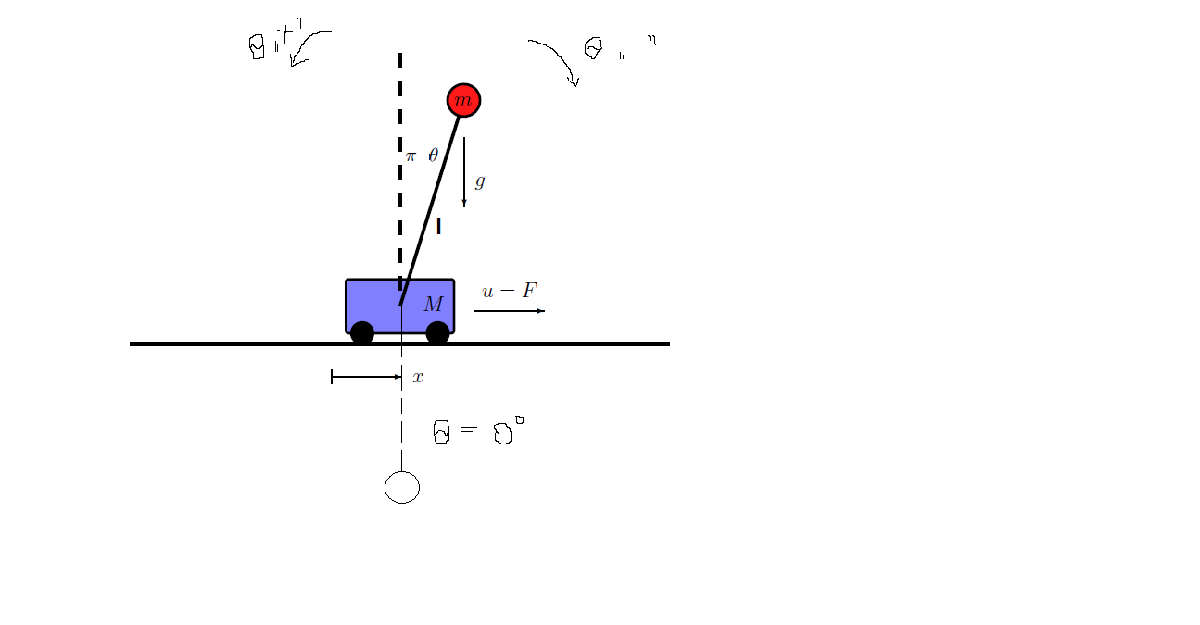

m = 1;      % mass of pendulum 
M = 5;      % mass of cart 
L = 2;      % length of pend 
g = -9.81;    
d = 1;      % coeefficient of friction
b = 1;      % cos(theta) for theta = pi

#### Equations:


$$$
x = 
\pmatrix{
       x \cr
       \dot{x} \cr
       \theta \cr
       \dot{\theta}
} 
= 
\pmatrix{
       x_1 \cr
       x_2 \cr
       x_3 \cr
       x_4
} 
\\

\ddot{x} = \frac{-m^2.l^2.g.cos(\theta).sin(\theta) + m.l^2(m.l.\dot{\theta}^2.sin(\theta) -b.\dot{x}) +m.l^2.F}{m.l^2(M+m(1-cos^2(\theta)))}\\
\ddot{\theta} = \frac{(m+M)m.g.l.sin(\theta)-m.l.cos(\theta)(m.l.\dot{\theta}^2.sin(\theta)-b.\dot{x})-m.l.cos(\theta).F}{m.l^2(M+m(1-cos^2(\theta)))}\\

\dot{x}_1 = x_2\\
\dot{x}_2 = \frac{-m^2.l^2.g.cos(x_3).sin(x_3) + m.l^2(m.l.x_4^2.sin(x_3) -b.x_2 +m.l^2.F}{m.l^2(M+m(1-cos^2(x_3)))}\\
\dot{x}_3 = x_4\\
\dot{x}_4 = \frac{(m+M)m.g.l.sin(x_3)-m.l.cos(x_3)(m.l.x_4^2.sin(x_3)-b.x_2)-m.l.cos(x_3).F}{m.l^2(M+m(1-cos^2(x_3)))}\\
$$$


#### Linearization:

% Linearizace kolem bodu theta = pi

A = [0 1 0 0;
    0 -d/M b*m*g/M 0;
    0 0 0 1;
    0 -b*d/(M*L) -b*(m+M)*g/(M*L) 0];
B = [0; 1/M; 0; b*1/(M*L)];
C = [[1 0 0 0];[0 0 1 0]];
D = [0; 0];
inv_pend_linsys = ss(A, B, C, D)

inv_pend_linsys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0    -0.2  -1.962       0
   x3       0       0       0       1
   x4       0    -0.1   5.886       0
 
  B = 
        u1
   x1    0
   x2  0.2
   x3    0
   x4  0.1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



% step(inv_pend_linsys)
[p, z] = pzmap(inv_pend_linsys)

p =          0
   -2.4077
   -0.2336
    2.4414



z =

  0×1 empty double column vector




% controllability: 
rank(ctrb(inv_pend_linsys))

ans = 4


% observability
rank(obsv(inv_pend_linsys))

ans = 4

#### LQR controller: 

% state cost matrix
global Q R S
Q = [[1 0 0 0]; [0 1 0 0]; [0 0 10 0]; [0 0 0 1]];                       % state cost matrix
R = 0.01;                           % input cost matrix
S = [[0]; [0]; [0]; [0]]            % state input weight matrix

S =      0
     0
     0
     0



global K
[K, W, ~] = lqr(inv_pend_linsys, Q, R, S)

K =   -10.0000  -22.7468  314.2601  123.4261


W =     2.1747    1.8596  -12.3426   -4.7192
    1.8596    3.1025  -22.1220   -8.4797
  -12.3426  -22.1220  198.7696   75.6700
   -4.7192   -8.4797   75.6700   29.3021


inv_pend_sys_lqr = ss(A-B*K, B, C, D)

inv_pend_sys_lqr =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       2   4.349  -64.81  -24.69
   x3       0       0       0       1
   x4       1   2.175  -25.54  -12.34
 
  B = 
        u1
   x1    0
   x2  0.2
   x3    0
   x4  0.1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.




% stability of new system:
eig(A-B*K)

ans =   -2.5891 + 0.5460i
  -2.5891 - 0.5460i
  -1.5473 + 0.0000i
  -1.2677 + 0.0000i


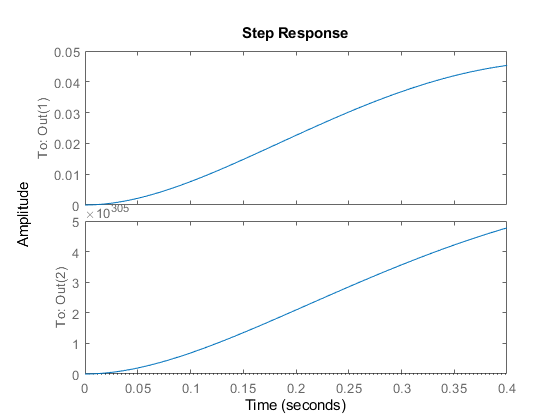


% !!! rescaling:

kr = -1./dcgain(inv_pend_sys_lqr);
kr(isinf(kr)) = realmax;     % subs inf for biggest double in matlab
inv_pend_sys_lqr.C = inv_pend_sys_lqr.C.*kr; 
step(inv_pend_sys_lqr)  

### simulation with LQR controller:

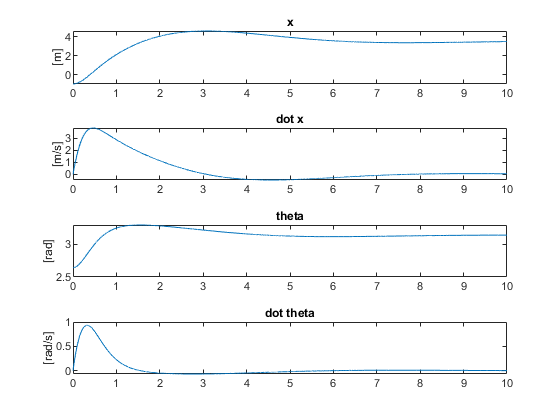

tspan = 0:.001:10;
global x0
x0 = [-1; 0; pi-0.5; 0]; % initial condition
sp = [3.5; 0; pi; 0];     % set point
[t,x_lqr] = ode45(@(t,x)inv_pend(x, LQR(x, sp)),tspan,x0);

tiledlayout(4,1)

ax1 = nexttile;
plot(ax1,t,x_lqr(:, 1))
title(ax1,'x')
ylabel(ax1,'[m]')

ax2 = nexttile;
plot(ax2,t,x_lqr(:, 2))
title(ax2,'dot x')
ylabel(ax2,'[m/s]')

ax3 = nexttile;
plot(ax3,t,x_lqr(:, 3))
title(ax3,'theta')
ylabel(ax3,'[rad]')

ax4 = nexttile;
plot(ax4,t,x_lqr(:, 4))
title(ax4,'dot theta')
ylabel(ax4,'[rad/s]')

### MPC:

#### discrete time model for MPC:

Ts = .001; % [s]

inv_pend_linsys_d = c2d(inv_pend_linsys, Ts, 'zoh')

inv_pend_linsys_d =
 
  A = 
               x1          x2          x3          x4
   x1           1   0.0009999  -9.809e-07   -3.27e-10
   x2           0      0.9998   -0.001962  -9.809e-07
   x3           0      -5e-08           1       0.001
   x4           0  -9.999e-05    0.005886           1
 
  B = 
              u1
   x1  9.999e-08
   x2     0.0002
   x3      5e-08
   x4  9.999e-05
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.




% step(inv_pend_linsys_d)

#### Calculation of optimal input for first moment:

global A_d B_d W_d
A_d = inv_pend_linsys_d.A;
B_d = inv_pend_linsys_d.B;
W_d = idare(A_d,B_d,Q,R,S)

W_d = 	1.0e+05 *

    0.0218    0.0186   -0.1234   -0.0472
    0.0186    0.0310   -0.2212   -0.0848
   -0.1234   -0.2212    1.9878    0.7567
   -0.0472   -0.0848    0.7567    0.2930



N = 100;                % horizont of prediction is 100 steps

up_0 = zeros([N,1]);    % initial input (optimised will be calculated)

% solving the optimisation problem, where JMPC is returning J (criterial
% func) and we have initial guess for optimal control (it's all zeros) and
% limits for "u": [-2, 2] [N]

% up_opt = fmincon(@(up)JMPC(x0,up,sp,A_d,B_d,Q,R,S,W_d),up_0,[],[],[],[],-2*ones(N,1),2*ones(N,1),[],optimset('Display','none'));

#### Simulation with non-linear model:

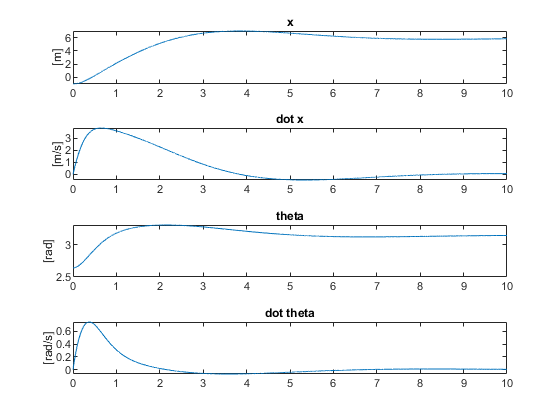

tspan = 0:Ts:10;

[t,x_mpc] = ode45(@(t,x)inv_pend(x, MPC(x, sp)),tspan,x0);
tiledlayout(4,1)

ax1 = nexttile;
plot(ax1,t,x_mpc(:, 1))
title(ax1,'x')
ylabel(ax1,'[m]')

ax2 = nexttile;
plot(ax2,t,x_mpc(:, 2))
title(ax2,'dot x')
ylabel(ax2,'[m/s]')

ax3 = nexttile;
plot(ax3,t,x_mpc(:, 3))
title(ax3,'theta')
ylabel(ax3,'[rad]')

ax4 = nexttile;
plot(ax4,t,x_mpc(:, 4))
title(ax4,'dot theta')
ylabel(ax4,'[rad/s]')

### Difference between LQR and MPC:

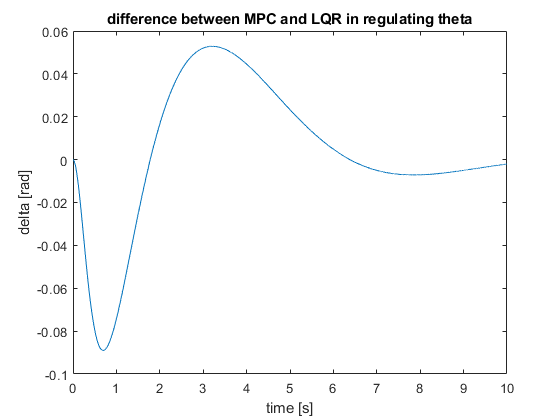

tiledlayout(1,1)

plot(t, x_mpc(:,3) - x_lqr(:,3))
title('difference between MPC and LQR in regulating theta')
xlabel('time [s]')
ylabel('delta [rad]')

# Inverted pendulum function definition (for simulating non-linear model):

function dx = inv_pend(x, F)

    M = 5;     % mass of the cart
    m = 1;     % mass of the pendulum
    b = 1;     % coefficient of the friction rotation
    g = -9.81;    % acceleration of gravity
    l = 2;     % length of shoulder of pendulum 
    
    Sx = sin(x(3));
    Cx = cos(x(3));
    denom = m*(l^2)*(M+m*(1-Cx^2));
    
    dx1 = x(2);
    dx2 = (-(m^2)*(l^2)*g*Cx*Sx + m*(l^2)*(m*l*(x(4)^2)*Sx) - b*x(2) + m*(l^2)*F)/denom;
    dx3 = x(4);
    dx4 = ((m+M)*m*g*l*Sx - m*l*Cx*(m*l*(x(4)^2)*Sx-b*x(2)) - m*l*Cx*F)/denom;
    
    dx = [dx1 dx2 dx3 dx4]';

end


# LQR regulator function definition:

function u = LQR(x, sp)
    global K
    u = -K*(x-sp);
end

# MPC regulator function definition:

function u = MPC(x, sp)

    x0 = x;                     % shifting the window

    N = 10;                     % horizont of prediction is 10 steps

    up_0 = 0*ones([N,1]);       % initial input (optimised will be calculated)

    % solving the optimisation problem, where JMPC is returning J (criterial
    % func) and we have initial guess for optimal control (it's all zeros) and
    % limits for "u": [-100 [N], 100[N] ] 
    
    global A_d B_d Q R S W_d
    up_opt = fmincon(@(up)JMPC(x0,up,sp,A_d,B_d,Q,R,S,W_d),up_0,[],[],[],[],-100*ones(N,1),100*ones(N,1),[],optimset('Display','none'));
    
    u = up_opt(1);

end